clear;
rng(123)%固定随机数

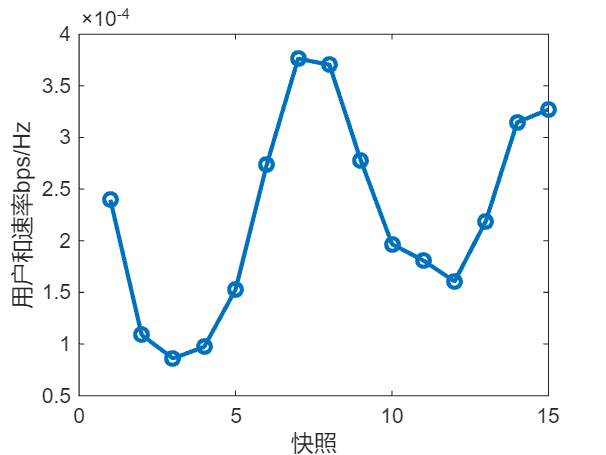

%计算预编码
load("narrowband_channels.mat")
users=5;
T=64;
R=2;
H=cell(users,15);
for j=1:15
    for k=1:users
        H{k,j}=zeros(R,T);
    end
end

for k=1:users
    for j=1:15
        %H{k,j}=H_snapshots(4*(k-1)+1:4*k,:,j);
        for r=1:R
            for t=1:T
                H{k,j}(r,t)=H_narrowband(r,t,k,j);
            end
        end
    end
end
F=cell(users,15);
sum_rate_wmmse=zeros(1,15);
for k=1:15
    H_temp=H(:,k);
    [F(:,k),sum_rate_wmmse(k)]=WMMSE(H_temp);
end
figure
plot(1:15,sum_rate_wmmse,'o-','LineWidth',2);
xlabel("快照");ylabel("用户和速率bps/Hz");

%将预编码矩阵转化成单位向量

vec_F=cell(1,15);
P=10;%发射功率
for k=1:15
    vec_F{k}=[];
    for kk=1:users
        vec_F{k}=[vec_F{k};F{kk,k}];
    end
    vec_F{k}=vec_F{k}/sqrt(P);%单位化
    vec_F{k}=[real(vec_F{k});imag(vec_F{k})];
end


ans = 1.1958

ans = 2.0593

ans = 1.9713

ans = 2.0123

ans = 2.0856

ans = 1.8432

ans = 2.0349

ans = 2.2130

ans = 1.7698

ans = 1.8739

ans = 2.2262

ans = 1.6958

ans = 2.3181

ans = 1.9980

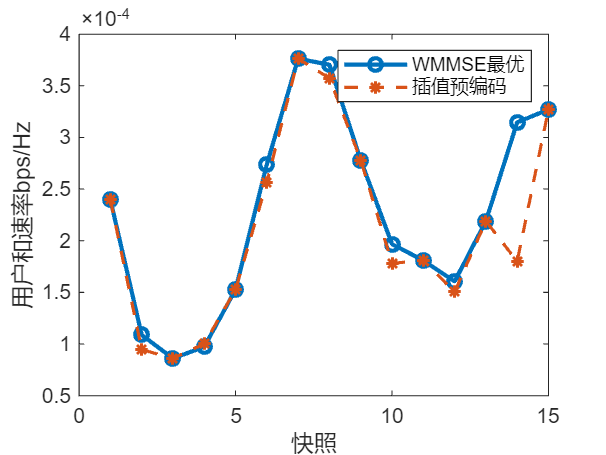

%内插

interp_p=1:2:15;%已知节点
predict_p=2:2:14;%预测节点
predict_F=cell(1,length(predict_p));
for k=1:length(predict_p)
    predict_F{k}=stiefel_C1_bezier_interpolation(vec_F(interp_p),k,0.5);
end

F_int=cell(users,length(predict_p));
for k=1:length(predict_p)
    predict_F{k}=predict_F{k}*sqrt(P);
end

for k=1:length(predict_p)
    for kk=1:users
        F_int{kk,k}=predict_F{k}(T*(kk-1)+1:T*kk)+1i*predict_F{k}(users*T+T*(kk-1)+1:users*T+T*kk);
    end
end


current_obj = zeros(1,15);
current_obj(interp_p)=sum_rate_wmmse(interp_p);
for kk=1:length(predict_p)
    for i = 1:users
        % 用户i的干扰加噪声协方差矩阵
        J_i = zeros(R, R);
        for j = 1:users
            if j ~= i
                J_i = J_i + H{i,2*kk} * F_int{j,kk} * F_int{j,kk}' * H{i,2*kk}';
            end
        end
        J_i = J_i +  eye(R);

        % 用户i的速率
        signal_cov = H{i,2*kk} * F_int{i,kk} * F_int{i,kk}' * H{i,2*kk}';
        R_i = real(log2(det(eye(R) + signal_cov / J_i)));
        current_obj(2*kk) = current_obj(2*kk) +  R_i;
    end
end


plot(1:15,sum_rate_wmmse,'o-','LineWidth',2);
hold on 
plot(1:15,current_obj,'*--','LineWidth',1.5);
hold off
legend("WMMSE最优","插值预编码") ;
xlabel("快照");ylabel("用户和速率bps/Hz");


rate_lost_mean=mean((sum_rate_wmmse(predict_p)-current_obj(predict_p))./sum_rate_wmmse(predict_p));
fprintf(" 插值节点平均和速率损失 %.2f %%", 100*rate_lost_mean);

 插值节点平均和速率损失 11.23 %

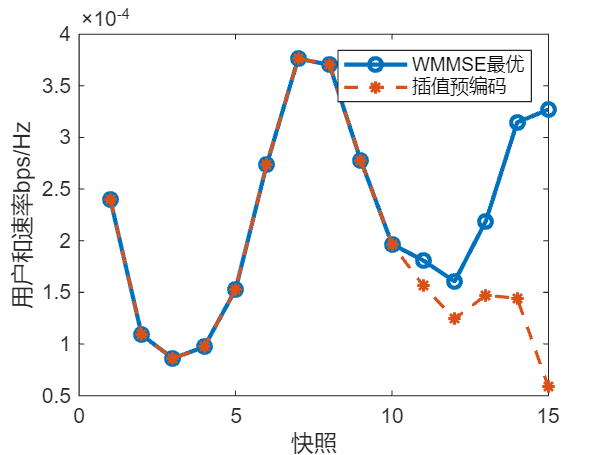

%外插
interp_p=1:10;
predict_p=11:15;
predict_F=cell(1,length(predict_p));
for k=1:length(predict_p)
    predict_F{k}=stiefel_C1_bezier_interpolation(vec_F(interp_p),length(interp_p),k);
end

F_int=cell(users,length(predict_p));
for k=1:length(predict_p)
    predict_F{k}=predict_F{k}*sqrt(P);
end

for k=1:length(predict_p)
    for kk=1:users
        F_int{kk,k}=predict_F{k}(T*(kk-1)+1:T*kk)+1i*predict_F{k}(users*T+T*(kk-1)+1:users*T+T*kk);
    end
end

current_obj = zeros(1,15);
current_obj(interp_p)=sum_rate_wmmse(interp_p);
for kk=1:length(predict_p)
    for i = 1:users
        % 用户i的干扰加噪声协方差矩阵
        J_i = zeros(R, R);
        for j = 1:users
            if j ~= i
                J_i = J_i + H{i,length(interp_p)+kk} * F_int{j,kk} * F_int{j,kk}' * H{i,length(interp_p)+kk}';
            end
        end
        J_i = J_i +  eye(R);

        % 用户i的速率
        signal_cov = H{i,length(interp_p)+kk} * F_int{i,kk} * F_int{i,kk}' * H{i,length(interp_p)+kk}';
        R_i = real(log2(det(eye(R) + signal_cov / J_i)));
        current_obj(length(interp_p)+kk) = current_obj(length(interp_p)+kk) +  R_i;
    end
end



figure
plot(1:15,sum_rate_wmmse,'o-','LineWidth',2);
hold on 
plot(1:15,current_obj,'*--','LineWidth',1.5);
hold off
legend("WMMSE最优","插值预编码") ;
xlabel("快照");ylabel("用户和速率bps/Hz");

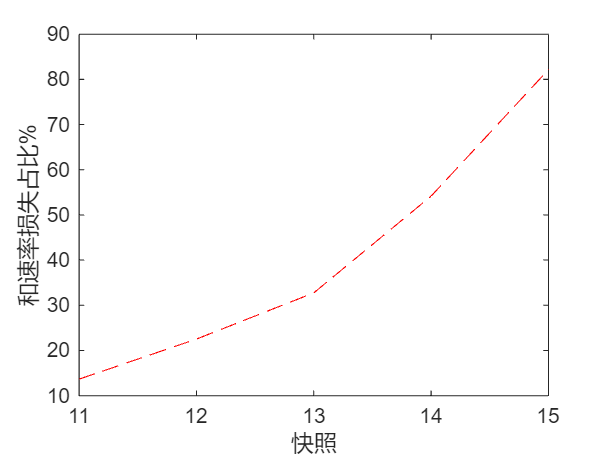



figure
plot(predict_p,100*(sum_rate_wmmse(predict_p)-current_obj(predict_p))./sum_rate_wmmse(predict_p),'r--');
xlabel("快照");ylabel('和速率损失占比%');

rate_lost_mean=mean((sum_rate_wmmse(predict_p)-current_obj(predict_p))./sum_rate_wmmse(predict_p));
fprintf(" 插值节点平均和速率损失 %.2f %%", 100*rate_lost_mean);

 插值节点平均和速率损失 41.05 %


function [F,sum_rate_wmmse]=WMMSE(H)
K = 1;          % 单小区
I = 5;          % 5个用户
T = 64;         % 发射天线数
R = 2;          % 每个用户的接收天线数
d = 1;          % 每个用户的数据流数
SNR_dB = 10;    % 信噪比 (dB)
P = 10^(SNR_dB/10); % 发射功率
max_iter = 1000; % 最大迭代次数
epsilon = 1e-4; % 收敛容差
% 权重设置 (所有用户平等)
alpha = ones(I, 1);
% 噪声功率 (所有用户相同)
sigma2 = 1;

V_wmmse = cell(I, 1);
for i = 1:I
    V_wmmse{i} = sqrt(P/(I*d)) * (randn(T, d) + 1j * randn(T, d)) / sqrt(2);
end

prev_obj = -inf;
for iter = 1:max_iter
    % 步骤1: 更新接收波束成形器 U (MMSE接收机)
    U = cell(I, 1);
    J = cell(I, 1);
    for i = 1:I
        % 计算干扰加噪声协方差矩阵
        J{i} = zeros(R, R);
        for j = 1:I
            J{i} = J{i} + H{i} * V_wmmse{j} * V_wmmse{j}' * H{i}';
        end
        J{i} = J{i} + sigma2 * eye(R);

        % MMSE接收机
        U{i} = J{i} \ (H{i} * V_wmmse{i});
    end

    % 步骤2: 更新权重矩阵 W
    W = cell(I, 1);
    E = cell(I, 1);
    for i = 1:I
        % 计算MSE矩阵
        E{i} = eye(d) - U{i}' * H{i} * V_wmmse{i};
        E{i} = E{i} * E{i}';
        for j = 1:I
            if j ~= i
                E{i} = E{i} + U{i}' * H{i} * V_wmmse{j} * V_wmmse{j}' * H{i}' * U{i};
            end
        end
        E{i} = E{i} + sigma2 * U{i}' * U{i};

        % 最优权重矩阵
        W{i} = inv(E{i});
    end

    % 步骤3: 更新发射波束成形器 V
    % 使用二分法求解最优mu
    mu_min = 0;
    mu_max = 1e6;
    mu_tol = 1e-14;

    for bisect_iter = 1:100
        mu = (mu_min + mu_max) / 2;

        % 计算公共矩阵 A
        A = zeros(T, T);
        for i = 1:I
            A = A + alpha(i) * H{i}' * U{i} * W{i} * U{i}' * H{i};
        end
        A = A + mu * eye(T);

        % 计算新的V
        V_new = cell(I, 1);
        total_power = 0;
        for i = 1:I
            V_new{i} = A \ (alpha(i) * H{i}' * U{i} * W{i});
            total_power = total_power + trace(V_new{i} * V_new{i}');
        end

        % 更新二分法区间
        if total_power > P
            mu_min = mu;
        else
            mu_max = mu;
        end

        if (mu_max - mu_min) < mu_tol
            break;
        end
    end
    V_wmmse = V_new;

    % 计算当前目标函数值 (加权和速率)
    current_obj = 0;
    for i = 1:I
        % 计算用户i的干扰加噪声协方差矩阵
        J_i = zeros(R, R);
        for j = 1:I
            if j ~= i
                J_i = J_i + H{i} * V_wmmse{j} * V_wmmse{j}' * H{i}';
            end
        end
        J_i = J_i + sigma2 * eye(R);

        % 计算用户i的速率
        signal_cov = H{i} * V_wmmse{i} * V_wmmse{i}' * H{i}';
        R_i = real(log2(det(eye(R) + signal_cov / J_i)));
        current_obj = current_obj + alpha(i) * R_i;
    end

    % 检查收敛
    if iter > 1 && abs(current_obj - prev_obj) < epsilon
        F=V_new;
        break;
    end
    prev_obj = current_obj;
end
F=V_new;
% 记录WMMSE的和速率
sum_rate_wmmse= current_obj;
end




function F_int=stiefel_C1_bezier_interpolation(F,num,t)
n=length(F);
v=cell(1,n-2);
for k=1:n-2
    vm=-stiefel_log_approx(F{k+1},F{k});
    vm=vm/norm(vm,'fro');
    vp=stiefel_log_approx(F{k+1},F{k+2});
    vp=vp/norm(vp,'fro');
    v_t=vm+vp;
    v{k}=v_t/norm(v_t,'fro');
end

A=zeros(n-2,n-2);
c=zeros(n-2,1);
inner_prod = @(X,Y) real(trace(X' * Y));
A(1,1:2)=[12*inner_prod(v{1},v{1}), 3*inner_prod(v{2},v{1})];
c(1)=3*inner_prod(stiefel_log_approx(F{2},F{3}),v{1})-2*inner_prod(stiefel_log_approx(F{2},F{1}),v{1});
for k=2:n-3
    A(k,k-1:k+1)=[inner_prod(v{k-1},v{k}) 4*inner_prod(v{k},v{k}) inner_prod(v{k+1},v{k})];
    c(k)=inner_prod(stiefel_log_approx(F{k+1},F{k+2})-stiefel_log_approx(F{k+1},F{k}),v{k});
end
A(n-2,n-3:n-2)=[3*inner_prod(v{n-3},v{n-2}) 12*inner_prod(v{n-2},v{n-2})];
c(n-2)=3*inner_prod(stiefel_log_approx(F{n-1},F{n-2}),v{n-2})-2*inner_prod(stiefel_log_approx(F{n-1},F{n}),v{n-2});
al=A\c;

if num==1
    Bm=stiefel_exp_approx(F{2},-1.5*al(1)*v{1});
    c01=stiefel_exp_approx(F{1},t*stiefel_log_approx(F{1},Bm));
    c12=stiefel_exp_approx(Bm,t*stiefel_log_approx(Bm,F{2}));
    F_int=stiefel_exp_approx(c01,t*stiefel_log_approx(c01,c12));
end
if num==n-1
    Bp=stiefel_exp_approx(F{n-1},1.5*al(n-2)*v{n-2});
    c01=stiefel_exp_approx(F{n-1},t*stiefel_log_approx(F{n-1},Bp));
    c12=stiefel_exp_approx(Bp,t*stiefel_log_approx(Bp,F{n}));
    F_int=stiefel_exp_approx(c01,t*stiefel_log_approx(c01,c12));
end
if num>1&&num<n-1
    Bp=stiefel_exp_approx(F{num},al(num-1)*v{num-1});
    Bm=stiefel_exp_approx(F{num+1},-al(num)*v{num});
    c01=stiefel_exp_approx(F{num},t*stiefel_log_approx(F{num},Bp));
    c12=stiefel_exp_approx(Bp,t*stiefel_log_approx(Bp,Bm));
    c23=stiefel_exp_approx(Bm,t*stiefel_log_approx(Bm,F{num+1}));
    c02=stiefel_exp_approx(c01,t*stiefel_log_approx(c01,c12));
    c13=stiefel_exp_approx(c12,t*stiefel_log_approx(c12,c23));
    F_int=stiefel_exp_approx(c02,t*stiefel_log_approx(c02,c13));
end
if num==n
    Bp=stiefel_exp_approx(F{n-1},1.5*al(n-2)*v{n-2});
    V_end=-2*stiefel_log_approx(F{n},Bp);
    F_int=stiefel_exp_approx(F{n},t*V_end);
end
end



function U = stiefel_log_approx(X, Y)
    % Stiefel流形对数映射（近似）
    % 对于St(n,1)（单位球面），使用球面对数映射

    n = size(X, 1);
    p = size(X, 2);

    if p == 1  % 单位球面情况
        % cos_theta = real(X' * Y);
        % cos_theta = max(-1, min(1, cos_theta));  % 数值稳定性
        cos_theta=X'*Y;
        theta = acos(cos_theta);

        if abs(theta) < 1e-10
            U = zeros(size(X));
        else
            U = (theta / sin(theta)) * (Y - cos_theta * X);
        end
    else
        % 一般Stiefel流形情况（简化处理）
        S = (eye(n) - X*X') * Y * pinv(X'*Y);
        U = X * real(logm(X'*Y)) + S;
    end
end

function Y=stiefel_exp_approx(X,U)
[n,p]=size(U);
[Q,R]=qr(U);
A=X.'*U;
T=[A,-R.';R,zeros(n,n)];
B=expm(T)*[eye(p);zeros(n,p)];
M=B(1:p,:);
N=B(p+1:p+n,:);
Y=X*M+Q*N;
end

